# calibra_anatomical

Reorient the obtained data so that they coincide approximately with the defined **anatomical standar orientation**. 

Taking as input a static signal -in which the only acceleration is that of gravity-, it calculates the rotation matrix that realigns the reference axes so that the first acceleration correspond to the vertical axes in the **anatomical standar orientation**.

## Syntax

`Mrot=calibra_anatomical(Acc_static)`

`Mrot=calibra_anatomical(Acc_static, R_approx)`

## Description

`Mrot``=calibra_anatomical(``Acc_static``) the` input parameter `Acc_static` is a matrix with triaxial accelerations recorded in a static position (used for calibration). It must be an nx3 matrix. 


$$\mathrm{acc}\;\mathrm{static}=\left\lbrack \begin{array}{ccc}
a_{\mathrm{x1}\;}  & a_{\mathrm{y1}}  & a_{\mathrm{z1}} \\
a_{\mathrm{x2}}  & a_{\mathrm{y2}}  & a_{\mathrm{z2}} \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$$


A rotation matrix is computed which can be used to change the sensor frame orientation to one where the first column is pointing against gravity. We call that the **anatomical standar orientation**.  

If sensor data stores as columns of a matrix (nx3), the way to obtain the data referred to this anatomical axes will be to make the multiplication:

       `dat_anat=(data_sensor*Mrot')`

       or 

       `dat_anat=(Mrot*sensor_data')'`

it is assumed that the sensor has been placed closely oriented to a **standar anatomical orientation, **defined as: 

- column 1 = vertical axis, superior direction (against gravity).

- column 2 = medio lateral axis, with changed sign acceleration

- column 3 = anteroposterior axis acceleration, anterior direction.

 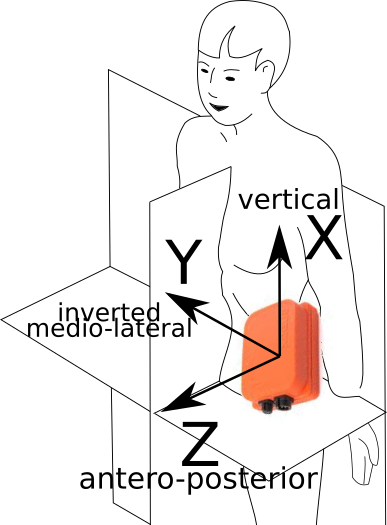 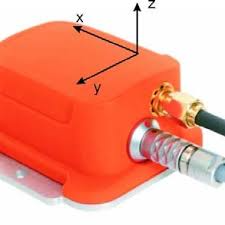

`--------------------------------------------------------------`

`Mrot``=calibra_antomical(``Acc_static, R_approx``) w`hen the sensor is not oriented close to the **standar anatomical orientation, **an estimation of the initial orientation must be provided, parameter `R_approx.` 

It can be used to provide this initial orientation in two different ways.

-  As a vector, with three numbers, indicating **in which column are placed **the antero-posterior, medio-lateral and vertical accelerations**,** respectively (with a negative sign if the axis is inverted). For example, a first-gen Xsens wired sensor as in the figure, its relation to the **standar orientation** corresponds to  `R_approx = `[ 3 , 1 , 2 ]

-  As a rotation matrix, to align the axes in the antero-posterior, medio-lateral and vertical order.

## Examples

% Cargamos los datos de un experimento de calibracion ya conocido:
filename = '../simur_data/test.log';
data=load(filename);
acc=data(:,2:4);
%Dibujamos los 500 primeros datos de aceleración
plot(acc(1:1000,:));
%Los primeros 250 datos los usamos para calibración. Son estáticos.
%La primera columna se corresponde aproximadamente con la aceleración
%vertical
%La segunda columna se corresponde aproximadamente con la mediolateral
%cambiada de signo
%La tercera columna se corresponde aproximadamente con la anteroposterior

%Definimos la rotación previa como :
R=[ 3 , -2, 1]; %columna ap, columna ml, columna vert

% Matriz de calibracion:
Mrot=calibra_anatomical(acc(1:250,:), R)
% Los datos calibrados son:
plot (acc(1:1000,:)*Mrot');
%Igualmente se calibran los giros o magnéticos
giro=data(:,5:7);
plot(giro(1500:2500,:)*Mrot');

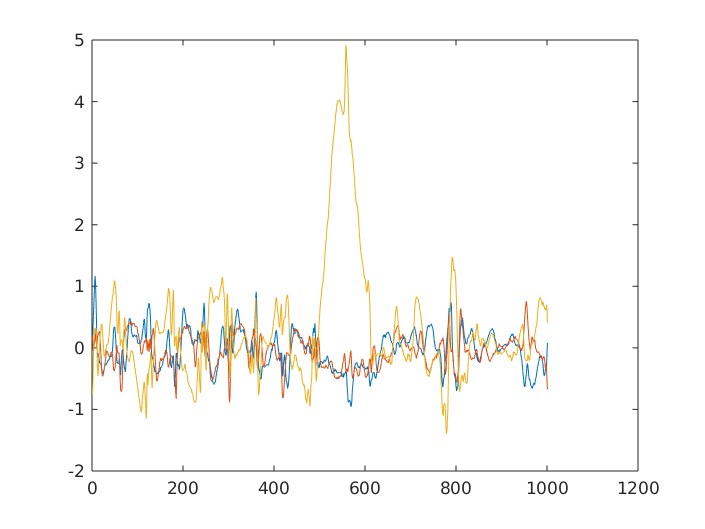

## Argumentos de entrada

%    AccStatic          - vector con la velocidad de giro en el eje mediolateral
%    Rapprox            - velocidad mínima a alcanzar para detectar eventos. Aconsejado 150

## Argumentos de salida

%    Mrot               - Rotation matrix